## Internal Cell checker

### **Internal cell checker with semi-supervised assistance**

EXTRACT has an internally built-in cell-check algorithm,  which employs semi-supervised machine learning methods to aid the user  with the cell checking process. The corresponding file is `cell_check.m`, which takes in two inputs: `M` and `output`. `M` is the movie, whereas `output` is the output generated by EXTRACT that contains cell maps and temporal traces. It has the following properties:

- The user can observe the cell maps during spiking times or click on  the temporal trace map to watch the raw movie during that time window.

- The user can decide whether a candidate is indeed a cell or not.

- The algorithm performs some computations in the background to assist the user, where the user can decide on some acceptance and rejection  thresholds.

- Once a small portion of cell candidates are checked, the algorithm  provides a guess for all the cell candidates. Thus, one does not need to check all the cells.

The figure below explains the process in 4 steps. In this  example, the user had checked only 5 cell candidates and EXTRACT  identified 18 cells and 6 non-cells. We note that this feature is still  experimental and we are constantly working to improve it. We are also  providing an external cell checker in case cell_check fails, which  usually happens when the number of EXTRACT partitions is larger than 1.

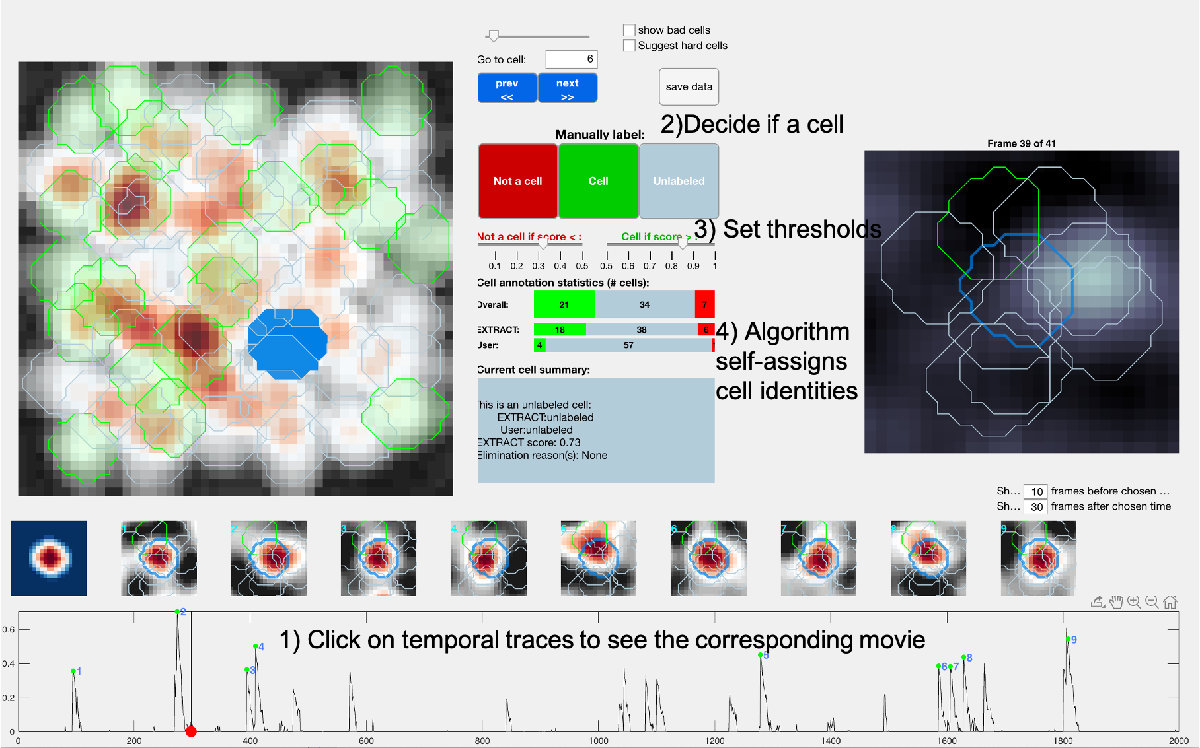

### **Try the cell check**

#### First, we will perform the cell finding from the Newcomer tutorial:

13-Dec-2023 20:22:21: Signal extraction will run on 1 partitions serially... 
13-Dec-2023 20:22:21: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.0203 
	 	 	 	 minimum magnitude: 0.0178 
	 	 	 20 cells found after a total of 21 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 20 (0 removed) 
	 	 	 End of iter # 2: # cells: 20 (0 removed) 
	 	 	 End of iter # 3: # cells: 20 (0 removed) 
	 	 	 End of iter # 4: # cells: 20 (0 removed) 
	 	 	 End of iter # 5: # cells: 20 (0 removed) 
	 	 	 End of iter # 6: # cells: 20 (0 removed) 
	 	 	 End of iter # 7: # cells: 20 (0 removed) 
	 	 	 End of iter # 8: # cells: 20 (0 removed) 
	 	 	 End of iter # 9: # cells: 20 (0 removed) 
	 	 	 End of iter # 10: # cells: 20 (0 removed) 


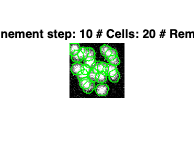

	 	 	 Providing raw traces... 
	 	 	 Count: 20 cells.
13-Dec-2023 20:22:45: Total of 20 cells are found.
13-Dec-2023 20:22:45: Removing duplicate cells...
13-Dec-2023 20:22:45: 20 cells were retained after removing duplicates.
13-Dec-2023 20:22:45: All done with EXTRACT! 


extract_root_directory = setup;
load(fullfile(extract_root_directory,'sample_data','example.mat'));
config = get_defaults([]); %calls the defaults
config.avg_cell_radius=7; %Average cell radius is 7.
%Movie is small enough that EXTRACT will not automatically partition this,
%but still a good idea to keep these in sight!
config.trace_output_option='raw'; % Choose 'nonneg' for non-negative Ca2+ traces, 'raw' for raw ones!
config.num_partitions_x=1;
config.num_partitions_y=1; 
%config.cellfind_filter_type='none'; % The movie is clean enough, no need for lowpass filtering
config.verbose=2; %Keeping verbose=2 gives insight into the EXTRACTion process, always advised to keep 2
config.spatial_highpass_cutoff=inf; % no need for highpass filtering
config.cellfind_filter_type ='none';
% Optionals whose defaults exist:
config.use_gpu=0; % This is a small dataset, will be fast on cpu anyways.
config.max_iter = 10; % 10 is a good number for this dataset
config.adaptive_kappa = 2;% Adaptive kappa is on for this movie. For an actual movie, keeping it off
config.cellfind_adaptive_kappa = 1;% Adaptive kappa is on for this movie. For an actual movie, keeping it off

% may be beneficial depending on the noise levels.
config.cellfind_min_snr=0.5;% Default snr is 1, lower this (never less than 0) to increase cell count at the expense of more spurious cells!
config.thresholds.T_min_snr=7;
config.visualize_cellfinding=1;

% Perform EXTRACTion:
output=extractor(M,config);

#### Now try the cell checker

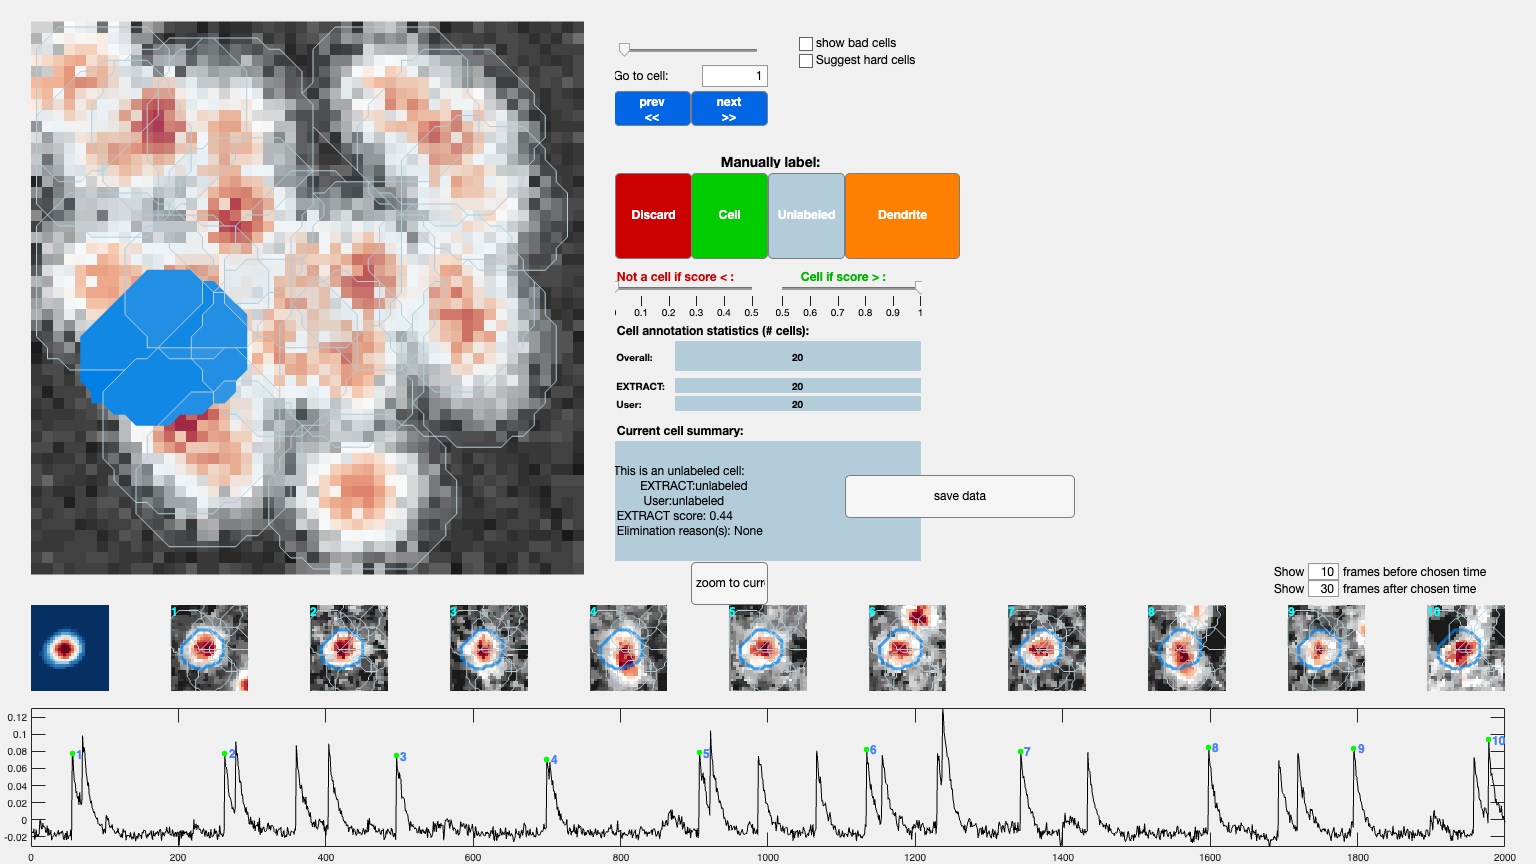

cell_check(output,M)